# Aliasing - what and how?

Let us have a look how aliasing "looks" like and what it sounds. We will generate a pure tone with a really high sampling frequency (just as a comparison) and then compare that one with a the same signal but sampled at a lower sampling frequency.

Let's generate the signal at a really high sampling frequency:

## Reference signal

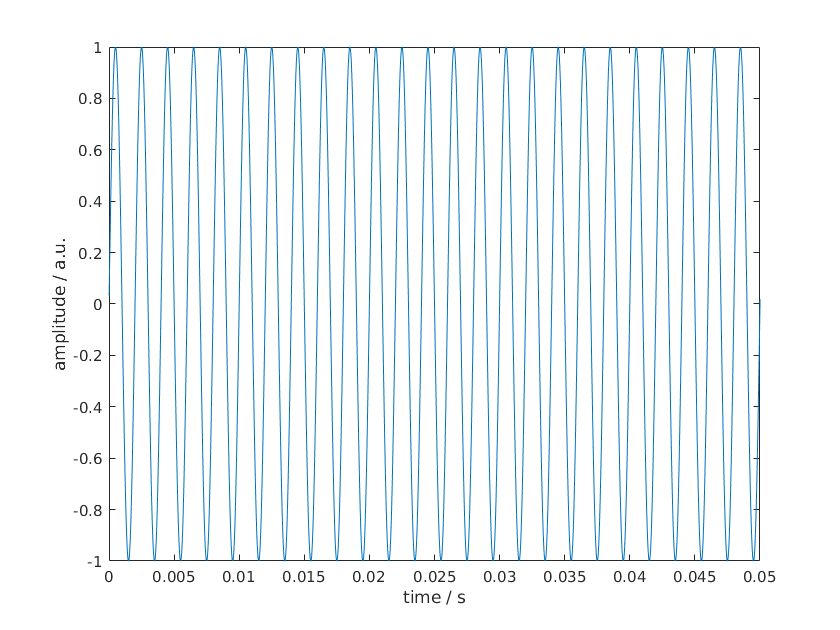


% Some parameters
T = 2;              % duration in seconds
fs_high = 100000;   % Yeah. Let's assume it is continuous :-); in Hz
f_tone = 500;         % tone frequency in Hz

% now we need to define the time points at which we want to "sample" our
% signal:
t_ref = 1/fs_high:1/fs_high:T-1/fs_high;    % a vector with time instances

% lets build the reference signal
sig_ref = sin(2*pi*f_tone*t_ref);           % here it is!

% plotting of reference signal
figure('Name',['Sampled tone of duration ', num2str(T), 's and frequency ' ...
                , num2str(f_tone), 'Hz']);

plot(t_ref, sig_ref);               % plotting and saving the figure "handle"
xlabel('time / s');
ylabel('amplitude / a.u.')
xlim([0 .05])                       % limit the time axis

What you now see looks like a continuous signal. It is not  but let's assume that the "continuous" signal looks like this (it is a fair approximation). In the next step, we will sample the signal at a lower sampling frequency. Change <fs> and see what happens - and uncomment the line where the playback comes. Check out if you can find a clear relation between <fs> and <f_tone>.

## Now at lower sampling frequency

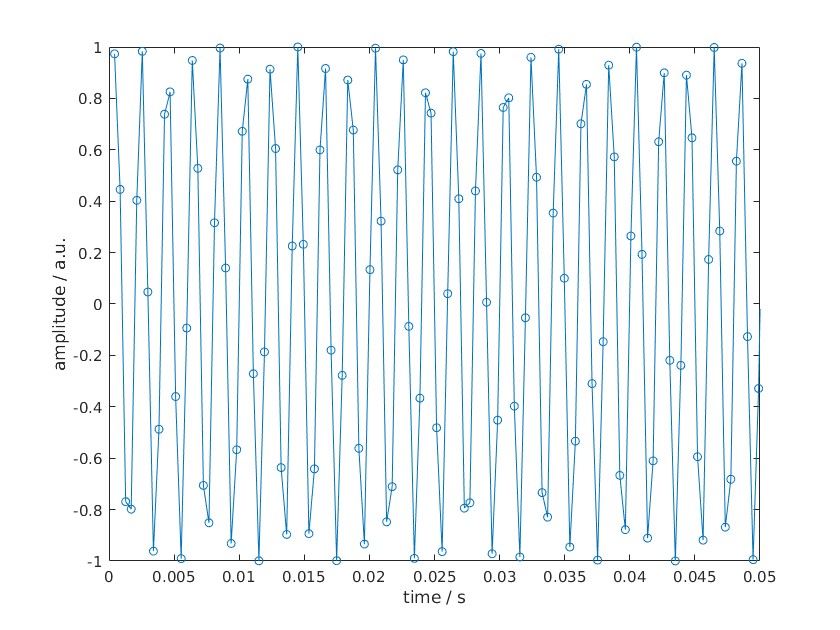

% Parameters of the sampled signal [HERE YOU CHANGE STUFF]
% ------------- CHANGE HERE --------------------------------
fs = 2345;                      % the "low" sampling frequency
% ----------------------------------------------------------
t = 1/fs:1/fs:T-1/fs;           % a vector with time instances

% let's generate the signal again
sig = sin(2*pi*f_tone*t);       % now with the time vector sampled with <fs>

figure('Name','''Reference Signal'' with sampled signal')

%plot on top - uncomment below to lines if you want
%plot(t_ref, sig_ref);           % plot the reference signal again  
%hold on;                        % this makes MATLAB plot into the same figure

plot(t, sig, 'o-')              % plot with circles and line
xlabel('time / s');
ylabel('amplitude / a.u.')
xlim([0 0.05])                  % limit the time axis


% try below instead of <plot(t, sig)> - this is the "real" way to plot it.
% stem(t, sig,'o')

% some stuff for audio playback - please ignore - this is to make your
% soundcard happy
sig_resample = resample(sig,44100,fs);

% Uncomment below if you want to listen to the sampled signals. CHECK YOUR
% HEADPHONE COLUME BEFORE!
%sound(.1*sig_resample,44100)


## Some questions

- What happens when you sample really high?

- What happens when you sample too low?

- What is the "critical" sampling frequency?

- Why is plotting with a line inbetween the samples not really correct?

- At which <fs> does the pitch (perceived tone height) change and at which doesn't it?